% Load the train data
filename='airline_train.csv';
df = readtable(filename,'VariableNamingRule','preserve');
df

df = 103594×24 table
    Var1    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ____    ______    _____________    ___


% Delete the first columns as it is not necesarry
df = removevars(df,{'Var1'});
df

df = 103594×23 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ______    _____________    ___    ______________    ___


% Devide dependent variable and independent variable
% Picked up the first 5000 variables for computational reasons
y = df(1:5000,23)

y = 5000×1 table
    satisfaction
    ____________

         0      
         0      
         1      
         0      
         1      
         0      
         0      
         1      
         0      
         0      
         0      
         0      
         0      
         1      
         0      
         0      


X = df(1:5000,1:20)

X = 5000×20 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness
    ______    _____________    ___    ______________    _____    _______________    _____________________    ___________________________


% Surrogate is turned off
tree = templateTree('Reproducible',true,'type','classification','Surrogate','off')

tree = Fit template for classification Tree.

        SplitCriterion: []
             MinParent: []
               MinLeaf: []
             MaxSplits: []
          NVarToSample: []
           MergeLeaves: []
                 Prune: []
        PruneCriterion: []
               QEToler: []
            NSurrogate: 'off'
                MaxCat: []
                AlgCat: []
    PredictorSelection: []
          UseChisqTest: []
                Stream: []
          Reproducible: 1
               Version: 2
                Method: 'Tree'
                  Type: 'classification'


|=======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | MaxNumSplits | NumVariables-|
|      | result |             | runtime     | (observed)  |              | ToSample     |
|=======================================================================================|
|    1 | Best   |      0.0586 |      21.634 |      0.0586 |         1940 |           18 |
|    2 | Accept |      0.1644 |      7.2974 |      0.0586 |            1 |            9 |
|    3 | Accept |      0.2192 |       7.961 |      0.0586 |            1 |           16 |
|    4 | Best   |      0.0568 |      22.294 |      0.0568 |          292 |           16 |
|    5 | Best   |      0.0562 |      21.001 |      0.0562 |         1940 |           12 |
|    6 | Accept |      0.0568 |      19.042 |      0.0562 |         4999 |            7 |
|    7 | Accept |      0.0882 |       10.77 |      0.0562 |         4999 |            1 |
|    8 | A

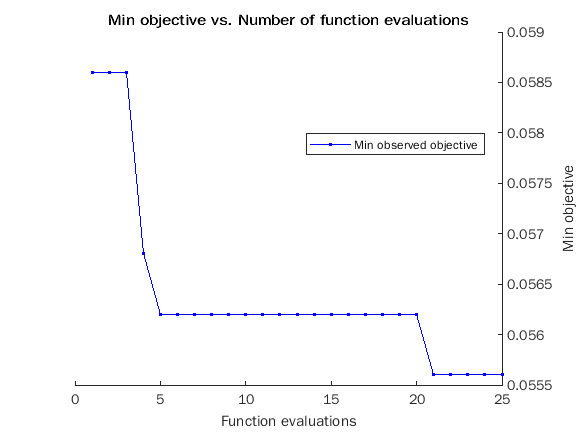


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 25 reached.
Total function evaluations: 25
Total elapsed time: 369.1907 seconds
Total objective function evaluation time: 357.3629

Best observed feasible point:
    MaxNumSplits    NumVariablesToSample
    ____________    ____________________

        292                  9          

Observed objective function value = 0.0556
Function evaluation time = 18.419



Mdl_HP_RF =   ClassificationBaggedEnsemble
                       PredictorNames: {1×20 cell}
                         ResponseName: 'satisfaction'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 5000
    HyperparameterOptimizationResults: [25×4 table]
                           NumTrained: 100
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: [5000×100 logical]


  

rng(2021); % For reproducibility
Mdl_HP_RF = fitcensemble(X,y,'Method','bag','Learners',tree, ...
    'OptimizeHyperparameters',{'NumVariablesToSample','MaxNumSplits'}, ...
    'HyperparameterOptimizationOptions', ...
    struct('Optimizer','gridsearch','KFold',10,'MaxObjectiveEvaluations',25))


% Save the model
save('Random_Forest_HP_tuning','Mdl_HP_RF');